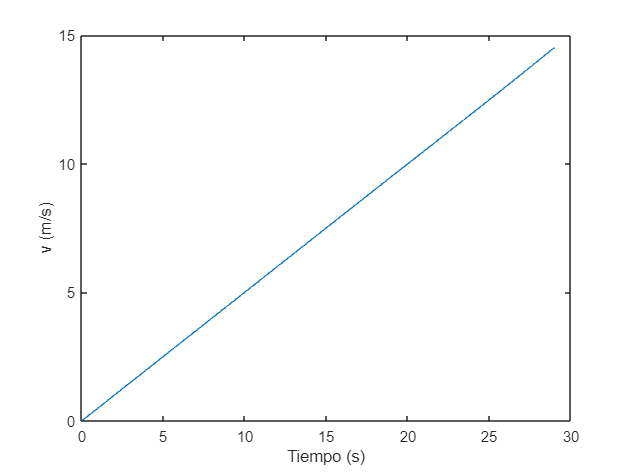

%Dinámica directa barco
clc
clear
%Datos
m=200;I=10000;d=5;
%Condiciones iniciales desplazamiento
x0=0;y0=0;Z0=0;
%Condiciones iniciales velocidad
xp0=0; Zp0=0;
%Condición inicial dependiente
yp0=xp0*tan(Z0);
%Fuerzas
F1=100;F2=30;
%tiempo integración
t0=29;
%funciones a integrar
vdpp=@(t,p)[p(4);p(5);p(6);F1;p(4)*p(6)/((cos(p(3)))^2);-F2*d];
%Matriz de masa
M=@(t,p)[eye(3) zeros(3);zeros(3) [m*cos(p(3)) m*sin(p(3)) 0;-tan(p(3)) 1 0;0 0 I]];

opt=odeset('Mass',M,'RelTol',1e-6);
[t,p]=ode45(vdpp,[0:0.001:t0],[x0;y0;Z0;xp0;yp0;Zp0],opt);
%se identifican las variables con la salida de la función ode45
x=p(:,1);
y=p(:,2);
Z=p(:,3);
figure;
v=sqrt(p(:,4).^2+p(:,5).^2);
plot(t,v)
xlabel('Tiempo (s)')
ylabel('v (m/s)')

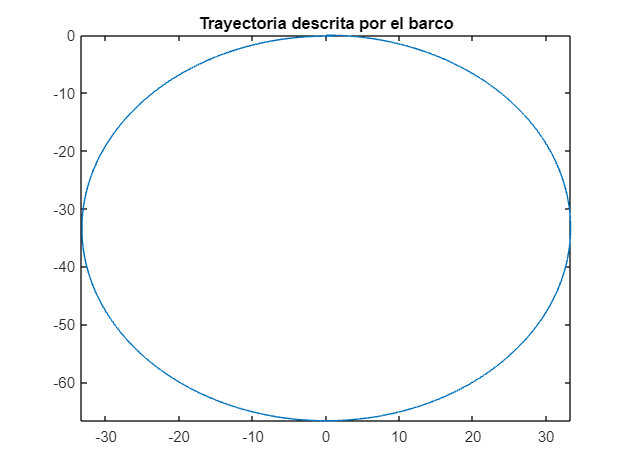

%Plot de la trayetoria descrita por el barco
figure;
plot(x,y)
axis tight
title('Trayectoria descrita por el barco')

%Cálculo de los radios de curvatura usando método gráfico
disp('El radio de curvatura medido en x es de :')

El radio de curvatura medido en x es de :


radX = (max(x)-min(x))/2

radX = 33.3030

disp('El radio de curvatura medido en y es de :')

El radio de curvatura medido en y es de :


radY = (max(y)-min(y))/2

radY = 33.3425

%Cálculo radio de curvatura usando cinemática, aceleración normal

thetapp = d*F2/I;
disp('El valor del radio de curvatura analítico es: ')

El valor del radio de curvatura analítico es: 


R = F1/(thetapp*m)

R = 33.3333